# average cascade calculation

%plot vortex example
plot(time, et,'k');
hold on;
plot(time,ev,'g--');
plot(time,eb,'r-.');

%vortex example
x1 = time(7); 
y1 = eb(7);
txt1 = '\leftarrow t1';
text(x1,y1,txt1);
%0.16
x2 = time(41);
y2 = 0.01;
txt2 = '\downarrow t_2';
text(x2,y2,txt2);
%0.288
x3 = time(73); 
y3 = eb(7);
txt3 = '\leftarrow t_3';
text(x3,y3,txt3);

%wave example
x1 = time(1); 
y1 = eb(1);
txt1 = '\leftarrow t1';
text(x1,y1,txt1);
%0
x2 = time(51);
y2 = eb(51);
txt2 = '\leftarrow t_2';
text(x2,y2,txt2);
%0
x3 = time(150); 
y3 = eb(150);
txt3 = '\leftarrow t_4';
text(x3,y3,txt3);

x3 = time(99); 
y3 = eb(99);
txt3 = '\uparrow t_3';
text(x3,y3,txt3);



set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.4, 2.55])
legend_handle=legend('{$E_t$}','{$E_u$}','{$E_b$}');
set(legend_handle,'Interpreter','latex','fontsize',11)
xlabel('time $t$ (s)','Interpreter','latex','fontsize',12)
%ylabel('$H_{0.01}/\lambda$','Interpreter','latex','fontsize',14)
%title('Pi @ 360 steps','fontsize',14)

%cascade plotting
legend_handle=legend('{Run $\rm I_a$}','{Run $\rm I_b$}','{Run $\rm I_c$}','Location', 'Best');
set(legend_handle,'Interpreter','latex','fontsize',10)
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.4, 2.55])
xlabel('$k$','Interpreter','latex','fontsize',12)
ylim([-0.1 1.1])

clear pivavr pibavr pitavr cavr c0avr
N=120;
averno=21;
%piv1=piv-c;
%pib1=pib+c;
%semilogx(piv1);hold on;semilogx(pib1);semilogx(pit);semilogx(c);
pivavr(1:N)=0;
pibavr(1:N)=0;
pitavr(1:N)=0;
cavr(1:N)=0;
tmp=0;
for i=1:N
for k=1:averno
    tmp=tmp+pivtotal((k-1)*(N+1)+i+1); 
end
pivavr(i)=tmp;
tmp=0;
end
pivavr=pivavr/averno;
pivavr=pivavr';


tmp=0;
for i=1:N
for k=1:averno
    tmp=tmp+pibtotal((k-1)*(N+1)+i+1); 
end
pibavr(i)=tmp;
tmp=0;
end
pibavr=pibavr/averno;
pibavr=pibavr';

tmp=0;
for i=1:N
for k=1:averno
    tmp=tmp+pittotal((k-1)*(N+1)+i+1); 
end
pitavr(i)=tmp;
tmp=0;
end
pitavr=pitavr/averno;
pitavr=pitavr';

for i=1:N
for k=1:averno
    tmp=tmp+ctotal((k-1)*(N+1)+i+1); 
end
cavr(i)=tmp;
tmp=0;
end
cavr=cavr/averno;
cavr=cavr';
c0avr(1:N)=0;

## for magnetic field


 for i=1:N
 for k=1:averno
     tmp=tmp+c0total((k-1)*(N+1)+i+1); 
 end
 c0avr(i)=tmp;
 tmp=0;
 end
 c0avr=c0avr/averno;
 c0avr=c0avr';
% for i=1:120
 %    ref(i)=0.18104;%0.0298775248  0.177798333 
% end


## plot cascade

pivavr1=pivavr-cavr;
pibavr1=pibavr+cavr;
if sum(c0avr)==0
    semilogx(pivavr1,'g--');hold on;semilogx(pibavr1,'r-.');semilogx(pitavr,'k');semilogx(cavr,'b');
   else
    semilogx(pivavr1,'g--');hold on;semilogx(pibavr1,'r-.');semilogx(pitavr,'k');semilogx(cavr+c0avr,'b');
end
legend_handle=legend('{$\langle \overline\Pi^u\rangle$}','{$\langle \overline\Pi^b\rangle$}','{$\langle\overline\Pi\rangle$}','{$\langle\overline {S}_{ij}\overline{B}_i\overline{B}_j\rangle$}');
set(legend_handle,'Interpreter','latex','fontsize',16)
xlabel('$k$','Interpreter','latex','fontsize',16)
%ylabel('$H_{0.01}/\lambda$','Interpreter','latex','fontsize',14)
%title('Pi @ 360 steps','fontsize',14)
%semilogx((pivavr1+pivavr1_new)/2);hold on;semilogx((pibavr1+pibavr1_new)/2);semilogx((pitavr+pitavr_new)/2);semilogx((cavr+c0avr+cavr_new+c0avr_new)/2);


%use for sin wave plots
fig = gcf;
if sum(c0avr)==0
    semilogx(pivavr1/1.4E-4,'g--');hold on;semilogx(pibavr1/1.4E-4,'r-.');semilogx(pitavr/1.4E-4,'k');semilogx(cavr/1.4E-4,'b');
   else
    semilogx(pivavr1/1.4E-4,'g--');hold on;semilogx(pibavr1/1.4E-4,'r-.');semilogx(pitavr/1.4E-4,'k');semilogx((cavr+c0avr)/1.4E-4,'b');
end
legend_handle=legend('{$\langle \overline\Pi^u\rangle$}','{$\langle \overline\Pi^b\rangle$}','{$\langle\overline\Pi\rangle$}','{$\langle\overline {S}_{ij}\overline{B}_i\overline{B}_j\rangle$}');
set(legend_handle,'Interpreter','latex','fontsize',16)
xlabel('$k$','Interpreter','latex','fontsize',16)
%ylabel('$H_{0.01}/\lambda$','Interpreter','latex','fontsize',14)
%title('P
ylim([-1 1]);

fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 4 3];


%this is for norm
piv_avr=pitavr(10);
pitavr_norm=pitavr/piv_avr;
pivavr1_norm=pivavr1/piv_avr;
pibavr1_norm=pibavr1/piv_avr;
cavr_norm=cavr/piv_avr;
c0avr_norm=c0avr/piv_avr;
figure(2);
if sum(c0avr)==0
    semilogx(pivavr1_norm,'g--');hold on;semilogx(pibavr1_norm,'r-.');semilogx(pitavr_norm,'k');semilogx(cavr_norm,'b');
   else
    semilogx(pivavr1_norm,'g--');hold on;semilogx(pibavr1_norm,'r-.');semilogx(pitavr_norm,'k');semilogx(cavr_norm+c0avr_norm,'b');
 end
legend_handle=legend('{$\langle \overline\Pi^u\rangle$}','{$\langle \overline\Pi^b\rangle$}','{$\langle\overline\Pi\rangle$}','{$\langle\overline {S}_{ij}\overline{B}_i\overline{B}_j\rangle$}');
set(legend_handle,'Interpreter','latex','fontsize',14)
xlabel('$k$','Interpreter','latex','fontsize',18)
hold on;
%add 0.5 reference
y_ref(1:N)=0.5;
semilogx(y_ref,'k');
fig = gcf;
fig.PaperUnits = 'inches';
hold off;

%%this is for 256, 512, 1024 integration
piv_avr=pitavr(10);
pitavr_norm256=pitavr/piv_avr;
pivavr1_norm256=pivavr1/piv_avr;
pibavr1_norm256=pibavr1/piv_avr;
cavr_norm256=cavr/piv_avr;
c0avr_norm256=c0avr/piv_avr;


piv_avr=pitavr(10);
pitavr_norm512=pitavr/piv_avr;
pivavr1_norm512=pivavr1/piv_avr;
pibavr1_norm512= pibavr1/piv_avr;
cavr_norm512=cavr/piv_avr;
c0avr_norm512=c0avr/piv_avr;

piv_avr=pitavr(10);
pitavr_norm1024=pitavr/piv_avr;
pivavr1_norm1024=pivavr1/piv_avr;
pibavr1_norm1024=pibavr1/piv_avr;
cavr_norm1024=cavr/piv_avr;
c0avr_norm1024=c0avr/piv_avr;

%%%%plot for 4 figures of different resolutions
% plot for total pi
% 
fig=gcf;
semilogx(pitavr_norm256,'k');hold on;semilogx(pitavr_norm512,'k--');semilogx(pitavr_norm1024,'k-.');
legend_handle1=legend('{Run $\rm  IV_a$}','{Run $\rm  IV_b$}','{Run $\rm  IV_c$}','Location', 'Best');
set(legend_handle1,'Interpreter','latex','fontsize',11)
xlabel('$k$','Interpreter','latex','fontsize',12)
ylim([-0.2 1.2])
fig.PaperUnits = 'inches';
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.4, 2.55])
hold off;
saveas(gcf,'diff_flux_1024_allflux.fig');

%%%%plot for 4 figures of different resolutions
% plot for u_pi
fig=gcf;
semilogx(pivavr1_norm256,'g');hold on;semilogx(pivavr1_norm512,'g--');semilogx(pivavr1_norm1024,'g-.');
y_ref(1:N)=0.5;
semilogx(y_ref,'k');
legend_handle1=legend('{Run $\rm  IV_a$}','{Run $\rm  IV_b$}','{Run $\rm  IV_c$}','Location', 'Best');
set(legend_handle1,'Interpreter','latex','fontsize',11,'Location', 'northeast');
xlabel('$k$','Interpreter','latex','fontsize',12)
ylim([-0.2 1.2])
fig.PaperUnits = 'inches';
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.4, 2.55])
hold off;
saveas(gcf,'diff_flux_1024_uflux.fig');

%%%%plot for 4 figures of different resolutions
% plot for b_pi
fig=gcf;
semilogx(pibavr1_norm256,'r');hold on;semilogx(pibavr1_norm512,'r--');semilogx(pibavr1_norm1024,'r-.');
y_ref(1:N)=0.5;
semilogx(y_ref,'k');
legend_handle1=legend('{Run $\rm  IV_a$}','{Run $\rm  IV_b$}','{Run $\rm  IV_c$}','Location', 'Best');
set(legend_handle1,'Interpreter','latex','fontsize',11,'Location', 'northeast');
xlabel('$k$','Interpreter','latex','fontsize',12)
ylim([-0.2 1.2])
fig.PaperUnits = 'inches';
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.4, 2.55])
hold off;
saveas(gcf,'diff_flux_1024_bflux.fig');

%%%%plot for 4 figures of different resolutions
% plot for b_pi
fig=gcf;
if sum(c0avr)==0
    semilogx(cavr_norm256,'b');hold on; semilogx(cavr_norm512,'b--');semilogx(cavr_norm1024,'b-.');
   else
    semilogx(cavr_norm256+c0avr_norm256,'b');hold on; semilogx(cavr_norm512+c0avr_norm512,'b--');semilogx(cavr_norm1024+c0avr_norm1024,'b-.');
 end
y_ref(1:N)=0.5;
semilogx(y_ref,'k');
legend_handle1=legend('{Run $\rm  IV_a$}','{Run $\rm  IV_b$}','{Run $\rm  IV_c$}','Location', 'Best');
set(legend_handle1,'Interpreter','latex','fontsize',11,'Location', 'southeast');
xlabel('$k$','Interpreter','latex','fontsize',12)
ylim([-0.2 1.2])
fig.PaperUnits = 'inches';
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.4, 2.55])
hold off;
saveas(gcf,'diff_flux_1024_conver.fig');



semilogx(pivavr1_norm256,'g--');hold on;semilogx(pibavr1_norm256,'r-.');semilogx(pitavr_norm256,'k');semilogx(cavr_norm256+c0avr_norm256,'b');
hold on;
legend_handle1=legend('{$\langle \overline {\Pi} \rangle$ Run $\rm I_a$}','{$\langle \overline {\Pi} \rangle$ Run $\rm I_b$}','{$\langle \overline {\Pi} \rangle$ Run $\rm I_c$}');
semilogx(pivavr1_norm512,'g--');hold on;semilogx(pibavr1_norm512,'r-.');semilogx(pitavr_norm512,'k');semilogx(cavr_norm512+c0avr_norm512,'b');
legend_handle2=legend('{$\langle \Pi^u(k)\rangle 512^3$}','{$\langle \Pi^b(K)\rangle$}','{$\langle\Pi(K)\rangle$}','{$\langle\partial_ju_i^{<K}B_i^{<K}B_j^{<K}\rangle$}');
semilogx(pivavr1_norm1024,'g--');hold on;semilogx(pibavr1_norm1024,'r-.');semilogx(pitavr_norm1024,'k');semilogx(cavr_norm1024+c0avr_norm1024,'b');
legend_handle3=legend('{$\langle \overline\Pi^u\rangle$}','{$\langle \overline\Pi^b\rangle$}','{$\langle\overline\Pi\rangle$}','{$\langle\overline {S}_{ij}\overline{B}_i\overline{B}_j\rangle$}');
semilogx(y_ref,'k');

fig=gcf;
legend_handle1=legend('{Run $\rm II_a$}','{Run $\rm II_b$}','{Run $\rm II_c$}','Location', 'Best');
set(legend_handle1,'Interpreter','latex','fontsize',11)
xlabel('$k$','Interpreter','latex','fontsize',12)
ylim([-0.2 1.2])
fig.PaperUnits = 'inches';
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 2.55, 2.55])
xlabel('$k$','Interpreter','latex','fontsize',12)
hold off;

## some legend



xlim([0 241]);
xlabel('k');
legend('U field energy transfer','B field energy transfer','total energy transfer','conversion');
legend('U field energy transfer','B field energy transfer','total energy transfer','conversion','conversion2');
legend('U field energy transfer','B field energy transfer','total energy transfer','conversion','conversion2','vdiss');
legend('U field energy transfer^{256}','B field energy transfer^{256}','total energy transfer^{256}','conversion^{256}','U field energy transfer^{512}','B field energy transfer^{512}','total energy transfer^{512}','conversion^{512}');
legend('U field energy transfer^{256}','B field energy transfer^{256}','total energy transfer^{256}','conversion^{256}','U field energy transfer^{512}','B field energy transfer^{512}','total energy transfer^{512}','conversion^{512}','U field energy transfer^{1024}','B field energy transfer^{1024}','total energy transfer^{1024}','conversion^{1024}');
tmp2=sum(bdiss);
semilogx(pivavr1_5,'--');hold on;semilogx(pibavr1_5,'--');semilogx(pitavr_5,'--');semilogx(cavr_5,'--');

semilogx(pivavr1,'--');hold on;semilogx(pibavr1,'--');semilogx(pitavr,'--');;semilogx(cavr+c0avr,'--');
semilogx(pivavr256,'--');hold on;semilogx(pibavr256,'--');semilogx(pitavr256,'--');;semilogx(cavr256,'--');
semilogx(pivavr512,'-.');hold on;semilogx(pibavr512,'-.');semilogx(pitavr512,'-.');;semilogx(cavr512,'-.');
semilogx(pivavr1024,'-');hold on;semilogx(pibavr1024,'-');semilogx(pitavr1024,'-');;semilogx(cavr1024,'-');

h_FigSpec1 = figure('Name','Eng','Units','centimeters','Position',[0 12 16 12]); %[Left Bottom Width Height]
pos = get(gca,'position');
set(gca,'position',[pos(1) 0.14 1.1*pos(3) 0.9*pos(4)]);
set(gca,'FontSize',10);
axis on;
figure(2);
plot(totale);hold on;plot(ke);plot(me);plot(vdiss);plot(bdiss);
legend('total energy','kinetic energy','magnetic energy','V field dissipation','B field dissipation');
xlabel('time steps/500');
ylabel('energy');

%% model spectrum plot
testx=(1:120);
testx=testx';
testy=testx.^(-5/3);

figure(3)
loglog(spece);hold on;loglog(specb);loglog(testy);
ylim([1E-14 10]);
xlim([0 120]);



pitavr1024=pitavr1024/0.2920
pibavr1024=pibavr1024/0.2920
pivavr1024=pivavr1024/0.2920
cavr1024=cavr1024/0.2920


## model spectrum plot


testx=(1:30);
testx=testx';
testy=testx.^(-5/3);

figure(3)
loglog(spece);hold on;loglog(specb);loglog(testy);
legend_handle=legend('{$E_v$}','{$E_b$}','{$-5/3$}');
set(legend_handle,'Interpreter','latex','fontsize',16)
ylim([1E-10 1]);
xlim([0 120]);


## averaged spectrum calculation

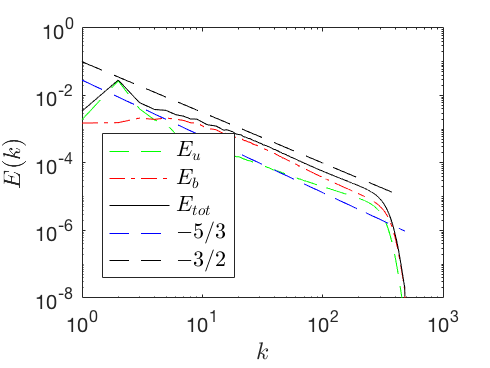


clear speceavr specbavr
N=482;
averno=3;

%calculate averaged spectrum

spece(1:N)=0;
specb(1:N)=0;

tmp=0;
for i=1:N
for k=1:averno
    tmp=tmp+specetotal((k-1)*(N+1)+i+1); 
end
speceavr(i)=tmp;
tmp=0;
end
speceavr=speceavr/averno;
speceavr=speceavr';

tmp=0;
for i=1:N
for k=1:averno
    tmp=tmp+specbtotal((k-1)*(N+1)+i+1); 
end
specbavr(i)=tmp;
tmp=0;
end
specbavr=specbavr/averno;
specbavr=specbavr';

spece_cum(1:N)=0.0;
specb_cum(1:N)=0.0;
for i=1:N
spece_cum(i)=sum(speceavr(1:i));
specb_cum(i)=sum(specbavr(1:i));
end
testx=(1:482);

testx=testx';
testy1=testx.^(-5/3);
testy2=testx.^(-3/2);
testy1=testy1/10;
testy2=testy2/2;
spectot=speceavr+specbavr;

%%fitting spectrum 
k=5:110;
lk = log(k);
ls = log(specbavr(5:110))';
p = polyfit(lk, ls, 1);
x_fitlin = linspace(0,4,2);
y_fitlin = p(1)*x_fitlin + p(2);
x_fitlog = exp(x_fitlin);
y_fitlog = exp(y_fitlin);

%legend('-5/3','U field','B field');
%spectotal_cum=spece_cum+specb_cum;
%semilogx(spece_cum);hold on;semilogx(specb_cum);semilogx(spectotal_cum);semilogx(pitavr);semilogx(pitavr+spectotal_cum');hold off;

writerObj = VideoWriter('vis_buffer.avi');
writerObj.FrameRate=5;
open(writerObj);
for K = [1, 200:200:7800]
  filename = sprintf('%d.png', K);
  thisimage = imread(filename);
  writeVideo(writerObj, thisimage);
end
close(writerObj);

outfreq=5
for i=1:81
xaxis(i)=0+i*outfreq;
end
xaxis=xaxis';
plot(xaxis,totale);hold on; plot(xaxis,ke);plot(xaxis,me);hold off;
xlabel('time step','fontsize',14)
legend_handle=legend('{$E_{total}$}','{$E_{vel}$}','{$E_{mag}$}');
set(legend_handle,'Interpreter','latex','fontsize',14)

% function four plot pi at different resolution
% 

function [] = plotPi(piType, legend, outputName)
    fig=gcf;
    if piType=='v'
        semilogx(pibavr1_norm256,'r');hold on;semilogx(pibavr1_norm512,'r--');semilogx(pibavr1_norm1024,'r-.');
    elseif piType=='b'
        semilogx(pibavr1_norm256,'r');hold on;semilogx(pibavr1_norm512,'r--');semilogx(pibavr1_norm1024,'r-.');
    elseif pitype=='c'
        if sum(c0avr)==0
            semilogx(cavr_norm256,'b');hold on; semilogx(cavr_norm512,'b--');semilogx(cavr_norm1024,'b-.');
        else
         semilogx(cavr_norm256+c0avr_norm256,'b');hold on; semilogx(cavr_norm512+c0avr_norm512,'b--');semilogx(cavr_norm1024+c0avr_norm1024,'b-.');
        end
    elseif pitype=='all'
        semilogx(pitavr_norm256,'k');hold on;semilogx(pitavr_norm512,'k--');semilogx(pitavr_norm1024,'k-.');
    end
    y_ref(1:N)=0.5;
    if pitype ~= 'all'
        semilogx(y_ref,'k');
    end
    legend1=strcat('Run $\rm  ',legend,'_a$');
    legend2=strcat('Run $\rm  ',legend,'_b$');
    legend3=strcat('Run $\rm  ',legend,'_c$');
    legend_handle1=legend(legend1,legend2,legend3,'Location', 'Best');
    set(legend_handle1,'Interpreter','latex','fontsize',11,'Location', 'northeast');
    xlabel('$k$','Interpreter','latex','fontsize',12)
    ylim([-0.2 1.2])
    fig.PaperUnits = 'inches';
    set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.4, 2.55])
    hold off;
    filepostion = strcat(outputname,pitype,'.fig')
    saveas(gcf,filepostion);
end